# Bespoke Noiuse Generator

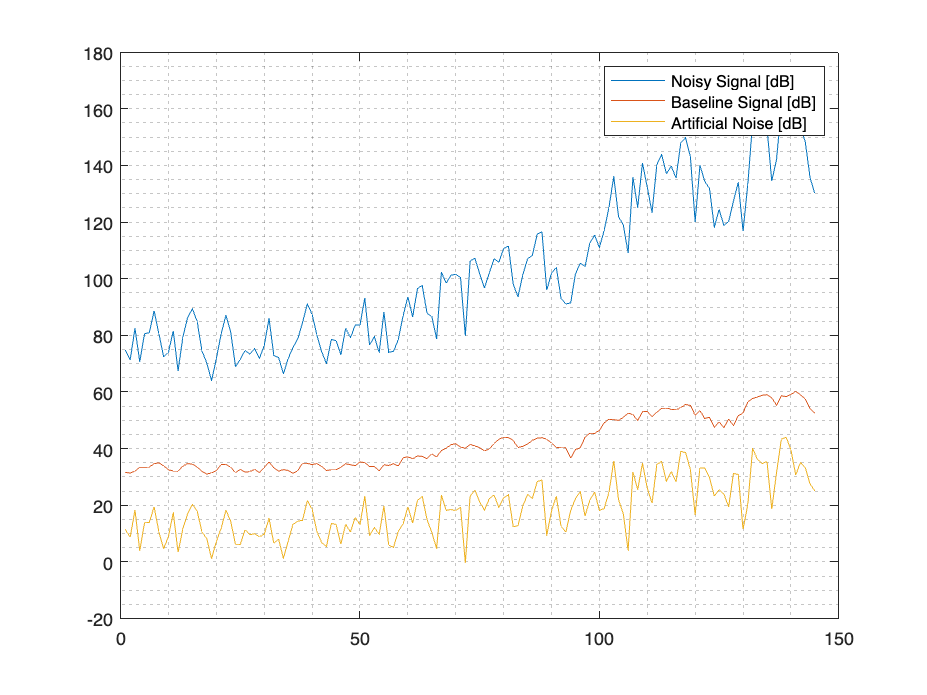

required_SNR_dB = 20; % Desired SNR in dB [dB].
required_SNR = (10^(required_SNR_dB / 10)); % converts dB to number.

% Calculate the power of the original signal
signalPower = (10.^(active_signal / 10));  % peak of each slice in number (not dB). the 'Signal' (S) for each slice.

% signalPower = mean(abs(S)).^2);  %%% This is your S as part of SNR.
%%% Hence if you are using just the peak of the signal define S as such. 
%%% Note that it takes the format of (abs(X).^2)
%%% '.^2' raises each element of the array 'abs(X)' to the power of 2.

% This calculates the noise power required to get to the desired SNR
noisePower = signalPower / required_SNR;

% This step makes a noise matrix that is the right power level and dimension.
noise = sqrt(noisePower/2) .* (randn(size(signalPower)) + 1i .* randn(size(signalPower)));
noise_abs = abs(noise);
noise_dB = 20*log10(abs(noise));
% Add the original matrix to the new noise matrix. Hopefully achieving the
% new desired SNR
noisyMatrix = signalPower .* noise_abs; % [number]
noisyMatrix_dB = 20*log10(noisyMatrix); % [dB]

figure
plot(1:length(noisyMatrix_dB), noisyMatrix_dB, ...
    1:length(active_signal), active_signal, ...
    1:length(noise_dB), noise_dB)
legend( 'Noisy Signal [dB]', 'Baseline Signal [dB]', 'Artificial Noise [dB]')
grid minor

%title(figure_title);
%ylabel('Doppler Velocity [m/s]');
%xlabel('Range (m)');

noisyMatrix_dB(1,1)

ans = 74.6928

active_signal(1,1)

ans = 31.6475

noise_dB(1,1)

ans = 11.3978

noisyMatrix(1,1)

ans = 5.4280e+03

signalPower(1,1)

ans = 1.4613e+03

noise_abs(1,1)

ans = 3.7144


mean_noisyMatrix_dB = mean(noisyMatrix_dB) % [dB]

mean_noisyMatrix_dB = 102.4927

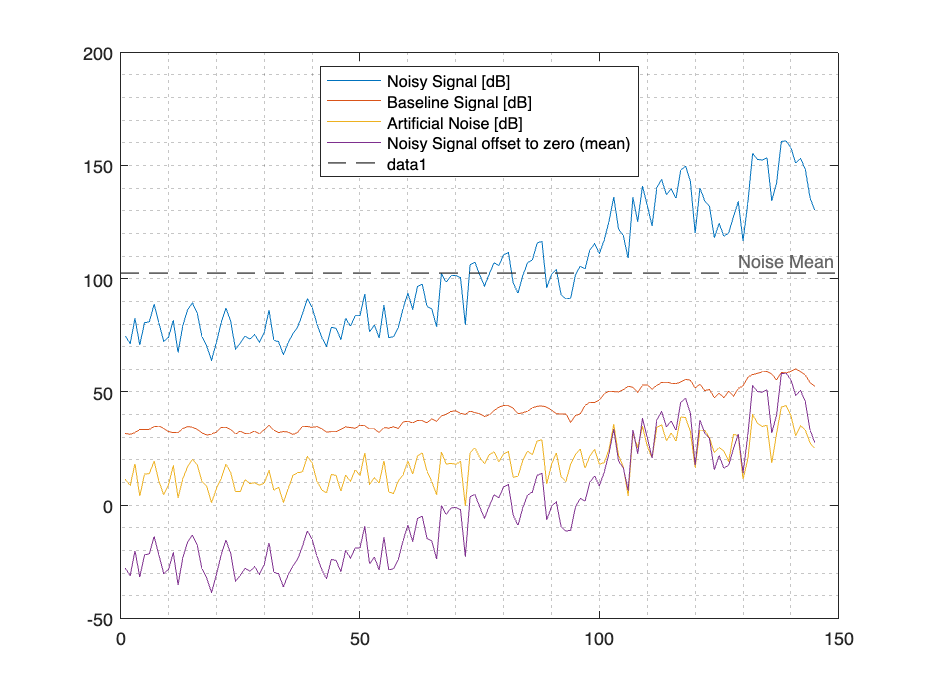

noisyMatrix_dB_zeroed = noisyMatrix_dB - mean_noisyMatrix_dB; % [dB]

figure
plot(1:length(noisyMatrix_dB), noisyMatrix_dB, ...
    1:length(active_signal), active_signal, ...
    1:length(noise_dB), noise_dB, ...
    1:length(noisyMatrix_dB_zeroed), noisyMatrix_dB_zeroed)
legend( 'Noisy Signal [dB]', 'Baseline Signal [dB]', 'Artificial Noise [dB]', 'Noisy Signal offset to zero (mean)', 'location', 'north')
yline(mean_noisyMatrix_dB, '--', 'Noise Mean', 'LineWidth', 1);
grid minor

%title(figure_title);
%ylabel('Doppler Velocity [m/s]');
%xlabel('Range (m)');